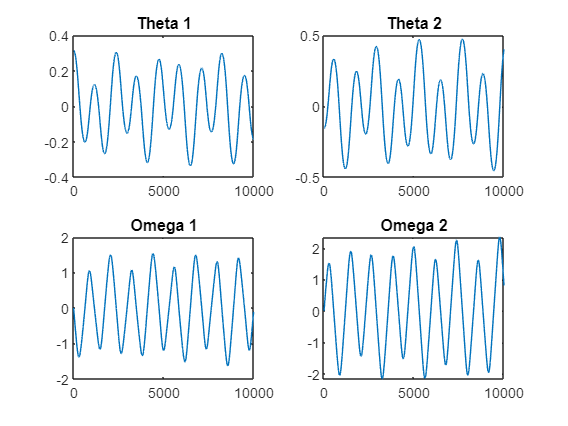

%%%Pendulum
%Forward scheme


% time step (s):
    dt=0.001;
% number of iterations:
    nmax=10000;
% weigths (kg):
    m1=0.05;
    m2=0.05;
% lengths (m):
    L1=1.0;
    L2=1.0;
% acceleration (m/s^-2):
    g=9.81;
% initial values of theta (rad):
    theta_1=pi()/10.0;
    theta_2=-pi()/20.0;
% initial values of omega (rad/s):
    omega_1=0.0;
    omega_2=0.0;

%initialisation
Values=zeros(4,nmax);%theta1,theta2,omega1,omega2
Values(:,1)=[theta_1,theta_2,omega_1,omega_2];


Omega1_prime=@(theta1,theta2,w1,w2) (-g*(2*m1+m2)*sin(theta1)-m2*g*sin(theta1-2*theta2)-2*sin(theta1-theta2)*m2*(w2^2*L2+w1^2*L1*cos(theta1-theta2)))/(L1*2*m1+m2-m2*cos(2*theta1-2*theta2));
Omega2_prime=@(theta1,theta2,w1,w2) (2*sin(theta1-theta2)*(w1^2*L1*(m1+m2)+g*(m1+m2)*cos(theta1)+w2^2*L2*m2*cos(theta1-theta2))/(L1*2*m1+m2-m2*cos(2*theta1-2*theta2)));

for i=2:nmax
    Values(3,i)= Values(3,i-1)+dt*Omega1_prime(Values(1,i-1),Values(2,i-1),Values(3,i-1),Values(4,i-1));
    Values(4,i)= Values(4,i-1)+dt*Omega2_prime(Values(1,i-1),Values(2,i-1),Values(3,i-1),Values(4,i-1));
    Values(1,i)= Values(1,i-1)+dt*Values(3,i-1);
    Values(2,i)= Values(2,i-1)+dt*Values(4,i-1);
end
figure,
subplot(2,2,1)
plot(Values(1,:))
title("Theta 1")
subplot(2,2,2)
plot(Values(2,:))
title("Theta 2")
subplot(2,2,3)
plot(Values(3,:))
title("Omega 1")
subplot(2,2,4)
plot(Values(4,:))
title("Omega 2")

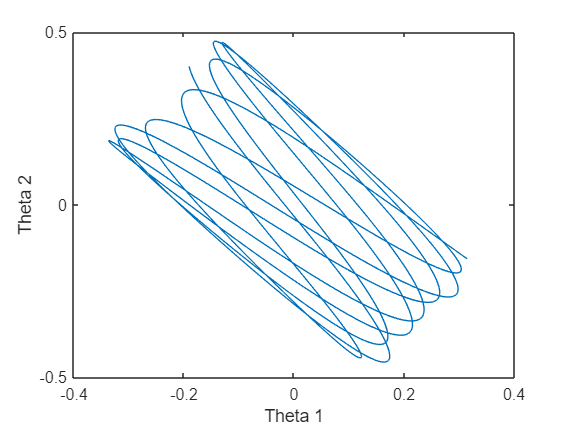


figure,
plot(Values(1,:),Values(2,:))
xlabel("Theta 1")
ylabel("Theta 2")

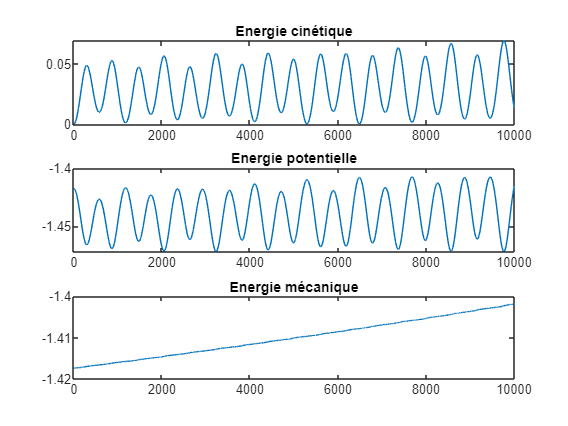


%energie mécanique
Em=zeros(1,nmax);
Ec=zeros(1,nmax);
Ep=zeros(1,nmax);
for i=1:nmax
    Ec(i)=1/2*m1*L1^2*Values(3,i)^2+1/2*m2*(L2^2*Values(4,i)^2+L1^2*Values(3,i)^2+2*L1*L2*Values(3,i)*Values(4,i)*cos(Values(1,i)-Values(2,i)));
    Ep(i)=-g*(m1+m2)*L1*cos(Values(1,i))-m2*g*L2*cos(Values(2,i));
    Em(i)=Ec(i)+Ep(i);
end
figure,
subplot(3,1,1);
plot(Ec)
title("Energie cinétique")
subplot(3,1,2);
plot(Ep)
title("Energie potentielle")
subplot(3,1,3);
plot(Em)
title("Energie mécanique")

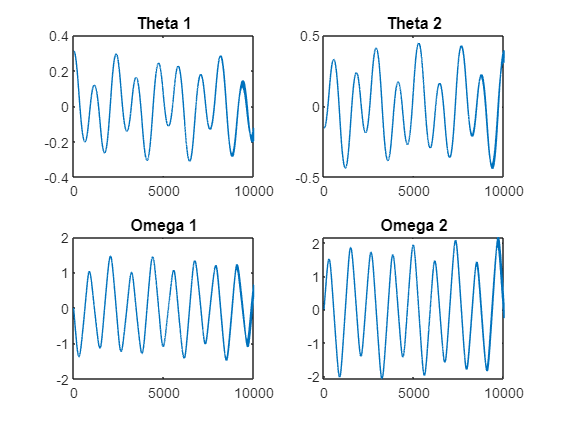

%Centered based scheme

% time step (s):
    dt=0.001;
% number of iterations:
    nmax=10000;
% weigths (kg):
    m1=0.05;
    m2=0.05;
% lengths (m):
    L1=1.0;
    L2=1.0;
% acceleration (m/s^-2):
    g=9.81;
% initial values of theta (rad):
    theta_1=pi()/10.0;
    theta_2=-pi()/20.0;
% initial values of omega (rad/s):
    omega_1=0.0;
    omega_2=0.0;

%initialisation
Values=zeros(4,nmax);%theta1,theta2,omega1,omega2
Values(:,1)=[theta_1,theta_2,omega_1,omega_2];
Values(:,2)=[0.314159265358979,-0.157079632679490,-0.00616053918232891,0.00702370270601780];


Omega1_prime=@(theta1,theta2,w1,w2) (-g*(2*m1+m2)*sin(theta1)-m2*g*sin(theta1-2*theta2)-2*sin(theta1-theta2)*m2*(w2^2*L2+w1^2*L1*cos(theta1-theta2)))/(L1*2*m1+m2-m2*cos(2*theta1-2*theta2));
Omega2_prime=@(theta1,theta2,w1,w2) (2*sin(theta1-theta2)*(w1^2*L1*(m1+m2)+g*(m1+m2)*cos(theta1)+w2^2*L2*m2*cos(theta1-theta2))/(L1*2*m1+m2-m2*cos(2*theta1-2*theta2)));

for i=3:nmax
    Values(3,i)= Values(3,i-2)+2*dt*Omega1_prime(Values(1,i-1),Values(2,i-1),Values(3,i-1),Values(4,i-1));
    Values(4,i)= Values(4,i-2)+2*dt*Omega2_prime(Values(1,i-1),Values(2,i-1),Values(3,i-1),Values(4,i-1));
    Values(1,i)= Values(1,i-2)+2*dt*Values(3,i-1);
    Values(2,i)= Values(2,i-2)+2*dt*Values(4,i-1);
end
figure,
subplot(2,2,1)
plot(Values(1,:))
title("Theta 1")
subplot(2,2,2)
plot(Values(2,:))
title("Theta 2")
subplot(2,2,3)
plot(Values(3,:))
title("Omega 1")
subplot(2,2,4)
plot(Values(4,:))
title("Omega 2")

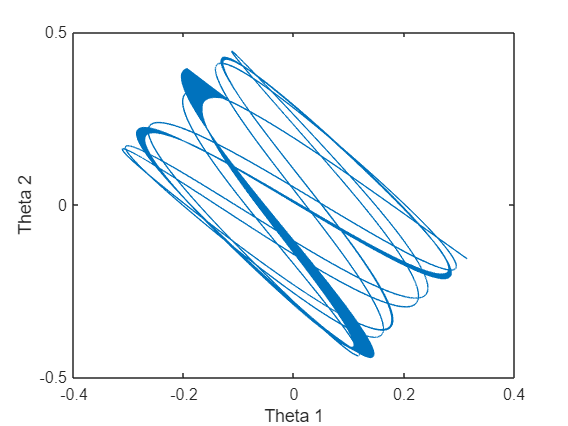


figure,
plot(Values(1,:),Values(2,:))
xlabel("Theta 1")
ylabel("Theta 2")

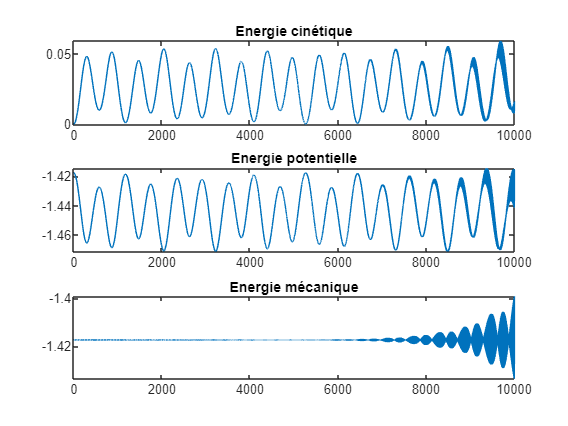


%energie mécanique
Em=zeros(1,nmax);
Ec=zeros(1,nmax);
Ep=zeros(1,nmax);
for i=1:nmax
    Ec(i)=1/2*m1*L1^2*Values(3,i)^2+1/2*m2*(L2^2*Values(4,i)^2+L1^2*Values(3,i)^2+2*L1*L2*Values(3,i)*Values(4,i)*cos(Values(1,i)-Values(2,i)));
    Ep(i)=-g*(m1+m2)*L1*cos(Values(1,i))-m2*g*L2*cos(Values(2,i));
    Em(i)=Ec(i)+Ep(i);
end
figure,
subplot(3,1,1);
plot(Ec)
title("Energie cinétique")
subplot(3,1,2);
plot(Ep)
title("Energie potentielle")
subplot(3,1,3);
plot(Em)
title("Energie mécanique")